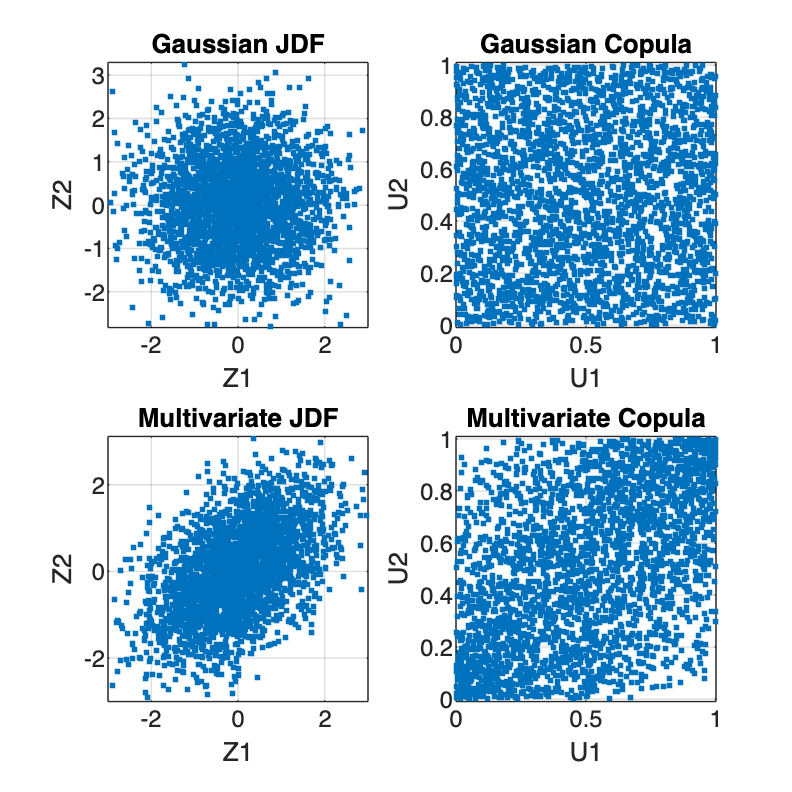

% Existing Code

% Define Bond Ratings, Probabilities, and Values
BondRating = ["AAA", "AA", "A", "BBB", "BB", "B", "C", "Default"];
Probability = [0.02, 0.33, 5.95, 86.93, 5.30, 1.17, 0.12, 0.18] / 100;
CumProbability = cumsum(Probability, 2, "reverse")';
BondValue = [109.37, 109.19, 108.66, 107.55, 102.02, 98.10, 83.64, 51.13];

% Create a Table with Bond Information
TblBond = table;
TblBond.Rating = BondRating';
TblBond.Probability = Probability';
TblBond.CumProbability = CumProbability;
TblBond.TransitionValue = BondValue';

% Define the Z Boundaries for Default Transitions (assuming N(0,1))
ZDefault = norminv(TblBond.Probability(8), 0, 1);
ZC = norminv(sum(TblBond.Probability(7:8)), 0, 1);
ZB = norminv(sum(TblBond.Probability(6:8)), 0, 1);
ZBB = norminv(sum(TblBond.Probability(5:8)), 0, 1);
ZBBB = norminv(sum(TblBond.Probability(4:8)), 0, 1);
ZA = norminv(sum(TblBond.Probability(3:8)), 0, 1);
ZAA = norminv(sum(TblBond.Probability(2:8)), 0, 1);
ZAAA = norminv(sum(TblBond.Probability(1:8)), 0, 1);

ZBoundary = [ZAAA, ZAA, ZA, ZBBB, ZBB, ZB, ZC, ZDefault];
TblBond.Z = ZBoundary';

% Generate Correlated Samples from a Copula
N = 1e5; % Number of simulations
DefaultRho = 0.5; % Correlation for multivariate case
rng('default');  % For reproducibility

% Correlation Matrices
CGaussian = [1 0; 0 1]; % Gaussian (no correlation)
CMultivariate = [1, DefaultRho; DefaultRho, 1]; % Multivariate with rho = 0.5

% Mean Variance Approach
ZGaussian = mvnrnd([0 0], CGaussian, N);
ZMultivariate = mvnrnd([0 0], CMultivariate, N);

% Copula Approach
UGaussian = copularnd('Gaussian', CGaussian, N); 
UMultivariate = copularnd('Gaussian', CMultivariate, N);

% Convert to standard normal for comparison
ZGaussian = norminv(UGaussian);
ZMultivariate = norminv(UMultivariate);

% Scatterplots of Gaussian and Multivariate Copula Samples
ISample = 1:3000; % Sample size for scatterplot display

figure();
set(gcf, 'Position', [0, 0, 600, 600]);

% Gaussian Joint Distribution Function (JDF)
subplot(2, 2, 1);
plot(ZGaussian(ISample, 1), ZGaussian(ISample, 2), '.');
axis([-3 3 -3 3]);
axis equal;
grid on;
title('Gaussian JDF');
xlabel('Z1');
ylabel('Z2');

% Gaussian Copula
subplot(2, 2, 2);
plot(UGaussian(ISample, 1), UGaussian(ISample, 2), '.');
axis([0 1 0 1]);
axis equal;
grid on;
title('Gaussian Copula');
xlabel('U1');
ylabel('U2');

% Multivariate Joint Distribution Function (JDF)
subplot(2, 2, 3);
plot(ZMultivariate(ISample, 1), ZMultivariate(ISample, 2), '.');
axis([-3 3 -3 3]);
axis equal;
grid on;
title('Multivariate JDF');
xlabel('Z1');
ylabel('Z2');

% Multivariate Copula
subplot(2, 2, 4);
plot(UMultivariate(ISample, 1), UMultivariate(ISample, 2), '.');
axis([0 1 0 1]);
axis equal;
grid on;
title('Multivariate Copula');
xlabel('U1');
ylabel('U2');


% Simulation and Expected Credit Loss Analysis

% Assume we have 2 bonds of equal value
NBonds = 2;
CurrentValueBond = Probability * BondValue';
CurrentValueBond2 = CurrentValueBond * NBonds;

% Prepare Storage for Future Bond Values
FutureBondValueGaussian = NaN(N, 2);
FutureBondValueMultivariate = NaN(N, 2);

% Cumulative Probability Boundaries for Defaults
CumProbabilityBoundary = [CumProbability; 0];

% Monte Carlo Simulation for Gaussian and Multivariate Cases
for i = 1:N
    % Gaussian Case
    IZ1 = find(CumProbabilityBoundary <= UGaussian(i, 1), 1, "first")-1;
    IZ2 = find(CumProbabilityBoundary <= UGaussian(i, 2), 1, "first")-1;
    FutureBondValueGaussian(i, :) = [BondValue(min(IZ1, 8)), BondValue(min(IZ2, 8))];
    
    % Multivariate Case
    IZ1 = find(CumProbabilityBoundary <= UMultivariate(i, 1), 1, "first")-1;
    IZ2 = find(CumProbabilityBoundary <= UMultivariate(i, 2), 1, "first")-1;
    FutureBondValueMultivariate(i, :) = [BondValue(min(IZ1, 8)), BondValue(min(IZ2, 8))];
end

% Portfolio PnL Calculation
PortfolioGaussian = sum(FutureBondValueGaussian, 2) - NBonds * CurrentValueBond;
PortfolioMultivariate = sum(FutureBondValueMultivariate, 2) - NBonds * CurrentValueBond;

% 99% VaR (Value at Risk) Calculation
GaussianVAR99 = prctile(PortfolioGaussian, 1);
MultivariateVAR99 = prctile(PortfolioMultivariate, 1);

% Expected Credit Loss Calculation
ExpectedLossGaussian = mean(PortfolioGaussian);
ExpectedLossMultivariate = mean(PortfolioMultivariate);

% Display Results
fprintf('Gaussian Model 99th Percentile VaR: %.5f\n', -GaussianVAR99);

Gaussian Model 99th Percentile VaR: 10.13584


fprintf('Multivariate Model 99th Percentile VaR: %.5f\n', -MultivariateVAR99);

Multivariate Model 99th Percentile VaR: 14.05584


fprintf('Gaussian Model Expected Credit Loss: %.5f\n', -ExpectedLossGaussian);

Gaussian Model Expected Credit Loss: 0.01145


fprintf('Multivariate Model Expected Credit Loss: %.5f\n', -ExpectedLossMultivariate);

Multivariate Model Expected Credit Loss: 0.00502


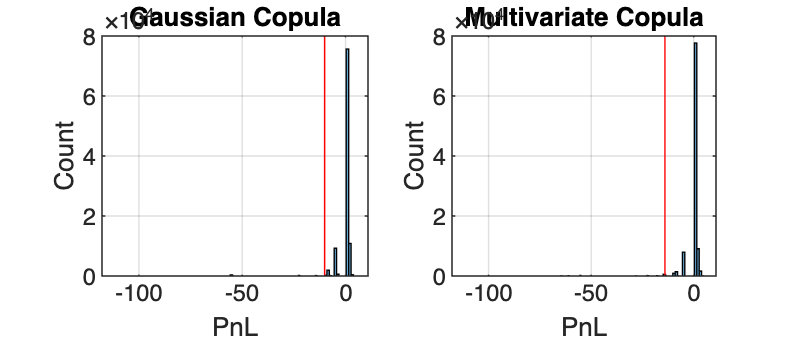


% Plot Histograms of Portfolio PnL for Gaussian and Multivariate Cases
figure();
set(gcf, 'Position', [0, 0, 700, 300]);

subplot(1, 2, 1);
histogram(PortfolioGaussian, 100);
hold on; line([GaussianVAR99, GaussianVAR99], get(gca, 'YLim'), 'color', 'r'); hold off;
title('Gaussian Copula');
ylabel('Count');
xlabel('PnL');
grid on;

subplot(1, 2, 2);
histogram(PortfolioMultivariate, 100);
hold on; line([MultivariateVAR99, MultivariateVAR99], get(gca, 'YLim'), 'color', 'r'); hold off;
title('Multivariate Copula');
ylabel('Count');
xlabel('PnL');
grid on;

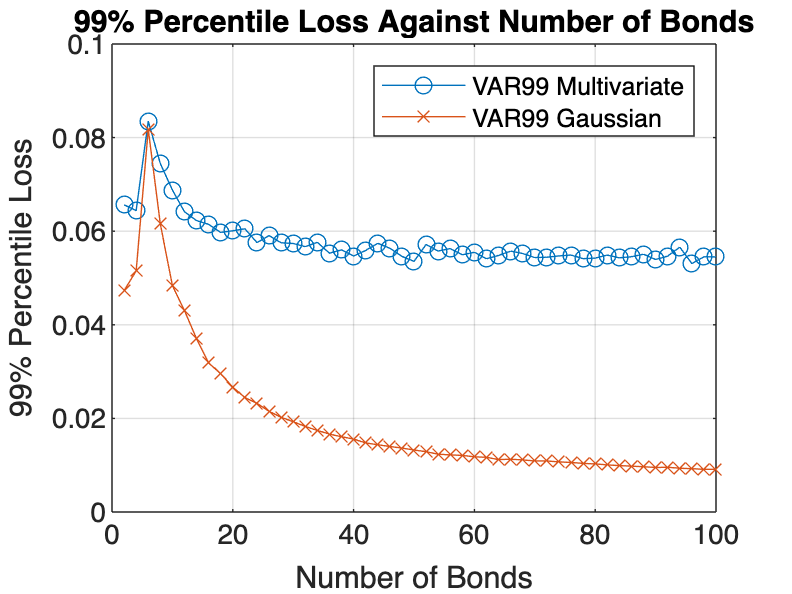


num_bonds_list = 2:2:100; % Range of bond counts
VAR99_Multivariate = zeros(size(num_bonds_list)); % Store 99% VaR results for multivariate case
VAR99_Gaussian = zeros(size(num_bonds_list)); % Store 99% VaR results for Gaussian case

for idx = 1:length(num_bonds_list)
    num_bonds = num_bonds_list(idx);
    
    % Create an identity and extended correlation matrix for Gaussian and multivariate cases
    CGaussian_extended = eye(num_bonds); % Gaussian (independent case)
    CMultivariate_extended = DefaultRho * ones(num_bonds) + (1 - DefaultRho) * eye(num_bonds); % Multivariate with correlation
    
    % Generate Gaussian and multivariate copula samples
    UGaussian = copularnd('Gaussian', CGaussian_extended, N); % Gaussian with no correlation
    UMultivariate = copularnd('Gaussian', CMultivariate_extended, N); % Multivariate with correlation
    
    % Calculate future bond values for Gaussian and multivariate cases
    FutureBondValueGaussian = NaN(N, num_bonds);
    FutureBondValueMultivariate = NaN(N, num_bonds);
    
    for i = 1:N
        for j = 1:num_bonds
            % Gaussian Case
            IZ = find(CumProbabilityBoundary <= UGaussian(i, j), 1, "first") - 1;
            FutureBondValueGaussian(i, j) = BondValue(min(max(IZ, 1), 8));
            
            % Multivariate Case
            IZ = find(CumProbabilityBoundary <= UMultivariate(i, j), 1, "first") - 1;
            FutureBondValueMultivariate(i, j) = BondValue(min(max(IZ, 1), 8));
        end
    end
    
    % Portfolio PnL for Gaussian and multivariate cases
    PortfolioGaussian = sum(FutureBondValueGaussian, 2) - num_bonds * CurrentValueBond;
    PortfolioGaussian = PortfolioGaussian / (num_bonds * CurrentValueBond);
    
    PortfolioMultivariate = sum(FutureBondValueMultivariate, 2) - num_bonds * CurrentValueBond;
    PortfolioMultivariate = PortfolioMultivariate / (num_bonds * CurrentValueBond);
    
    % Calculate 99% VAR for Gaussian and multivariate cases
    VAR99_Gaussian(idx) = prctile(PortfolioGaussian, 1);
    VAR99_Multivariate(idx) = prctile(PortfolioMultivariate, 1);
end

% Plot 99% VaR against the number of bonds
figure;
plot(num_bonds_list, -VAR99_Multivariate, '-o', 'DisplayName', 'VAR99 Multivariate');
hold on;
plot(num_bonds_list, -VAR99_Gaussian, '-x', 'DisplayName', 'VAR99 Gaussian');
xlabel('Number of Bonds');
ylabel('99% Percentile Loss');
title('99% Percentile Loss Against Number of Bonds');
legend('show'); % Adds a legend to differentiate the two lines
grid on;
hold off;